clear
load data3.mat
n=length(data.CzasLokalnyUTC0100);
T=60; %[s]
fs=1/T; %[Hz]
t=T*(0:n-1);
Kompresor1=data.StanKompresor;
StanCzujnikaZamkniecia=data.StanCzujnikZamkniciaDrzwi;
TemperaturaOtoczenia=0.1*data.TemperaturaOtoczenia;
Wlot=0.1*data.TemperaturaSterujca;
X=[Kompresor1,StanCzujnikaZamkniecia,...
    TemperaturaOtoczenia,Wlot]';

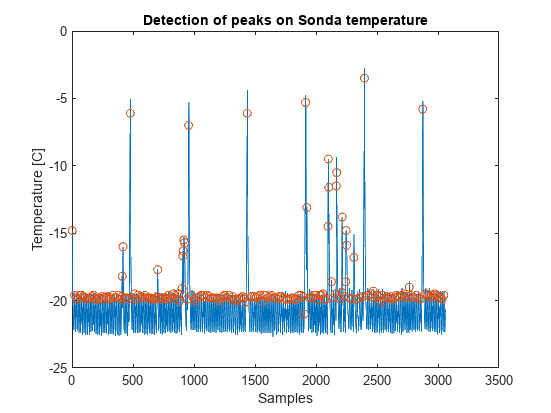

locs=compressorCycles(X(1,:));
x = FeatureExtract(X(4,:),locs);
plot((X(4,:)));hold on
plot(locs,(X(4,locs)),'o');hold off
title('Detection of peaks on Sonda temperature')
xlabel('Samples')
ylabel('Temperature [C]')

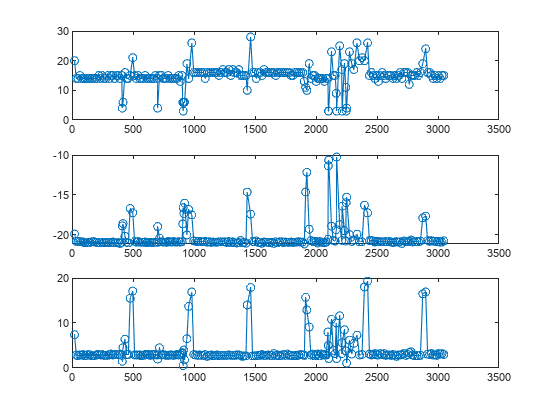

f1=zeros(1,length(locs)-1);
for i=1:length(locs)-1
    f1(i)=locs(i+1)-locs(i);
end
locs=locs(2:end);
figure 
subplot(311)
plot(locs,f1,'o-')
subplot(312)
plot(locs,x(3,:),'o-')
subplot(313)
plot(locs,x(1,:)-x(2,:),'o-')

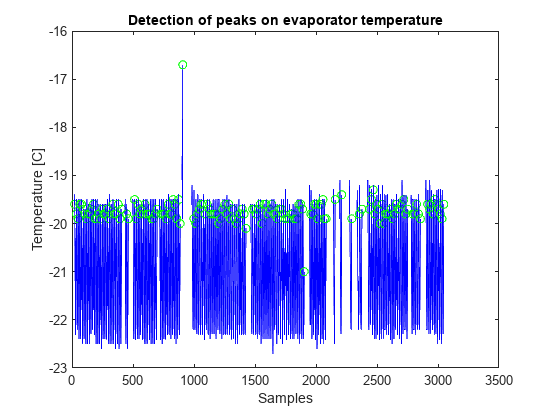

fridge_air_temp_p2p=x(1,:)-x(2,:);
indexContainer=cell(1);
indexContainer{1}=[];
set=1;
figure
TF = isoutlier(fridge_air_temp_p2p);
plot(locs(1),(X(4,locs(1))),'Marker','o',"Color",'green');hold on
for i=2:length(x)
    
    if (TF(i)==0)
        plot(locs(i-1):locs(i),(X(4,locs(i-1):locs(i))),"Color",'blue');
        plot(locs(i),(X(4,locs(i))),'Marker','o',"Color",'green');
        indexContainer{set}=[indexContainer{set},locs(i-1):locs(i)];
    else
        if TF(i-1)==0
            set=set+1;
            indexContainer{set}=[];
        end
    end
end
% plot(locs,(X_filtered(4,locs)),'Marker','o',"Color",'green');
hold off
title('Detection of peaks on evaporator temperature')
xlabel('Samples')
ylabel('Temperature [C]')

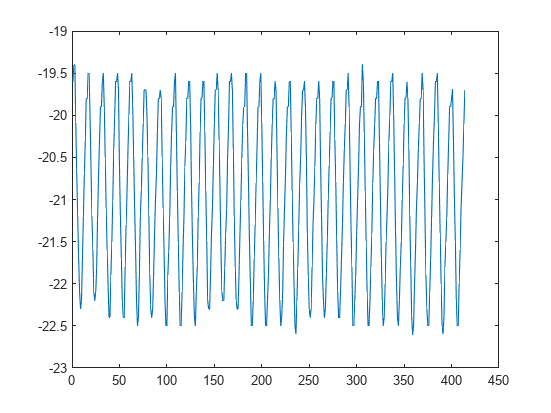

figure
plot(X(4,indexContainer{1}))

set=1;
for i = 1:length(indexContainer)
    if length(indexContainer{i})>60
        usableDataIndex{set}=indexContainer{i};
        set=set+1;
    end
end

% for i = 1:length(usableDataIndex)
for i = 1:3
    t_sim=T*(0:length(usableDataIndex{i})-1);
    [y{i},params{i}]=GATrain(X(1,usableDataIndex{i}), X(3,usableDataIndex{i}),...
        t_sim, X(4,usableDataIndex{i}(1)), X(4,usableDataIndex{i}));
end

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.
Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


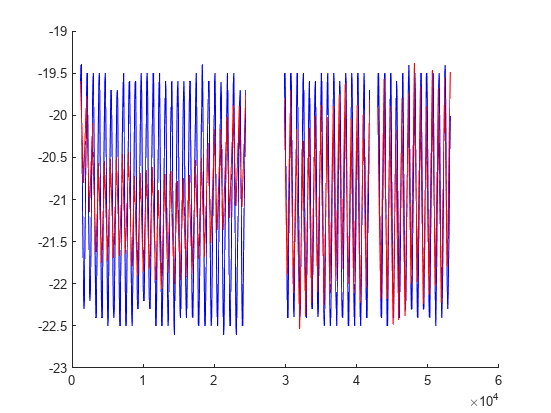

figure
hold on
% for i = 1:length(usableDataIndex)
for i = 1:3
    plot(t(usableDataIndex{i}),X(4,usableDataIndex{i}),'b')
    plot(t(usableDataIndex{i}),y{i},'Color','red')
end
hold off

Multiple runs show great variability in performance and repeatability